## `Robotics, Vision, Mechatronics for Manufacturing`

### Lab 1: Aditya Mahendru, Keeranat Kolatat, Munzir Abdulmajid

Reading: Chap 7.3-7.5

Please submit all your MATLAB codes. 				

% UW Mechanical Engineering
% Robotics, Visiton, and Mechatronics for Manufacturing, Sp 2021
% HW2 / Lab1
% Warning: This piece of code is not complete. Fill the blanks and add your
% own code to answer the raised questions in the HW.
% Please install Robotics Toolbox first: https://petercorke.com/toolboxes/robotics-toolbox/

1. Picking trajectory generation for Puma 560 robot. 

(a)  Import puma 560 model and visualize the following three configurations defined in joint space: 

i. Zero joint position: q1 = (0, 0, 0, 0, 0, 0). 							

ii. Arm-up position: q2 = (0, π/2, −π/2, 0, 0, 0). 

iii. Stretch position: q3 = (0, 0, π/2, 0, 0, 0). 		

%% Load puma 560 model
mdl_puma560

%% Visualize poses
q1 = [0, 0, 0, 0, 0, 0];         % zero angles
q2 = [0, pi/2, -pi/2, 0, 0, 0];  % ready pose, arm up
q3 = [0, 0, -pi/2, 0, 0, 0];     % stretch position
% set azimuth and elevation angle
ae_angle = [138, 30];
%Zero joint position
p560.plot3d(q1, 'view', ae_angle) 

Loading STL models from ARTE Robotics Toolbox for Education  by Arturo Gil (http://arvc.umh.es/arte).......


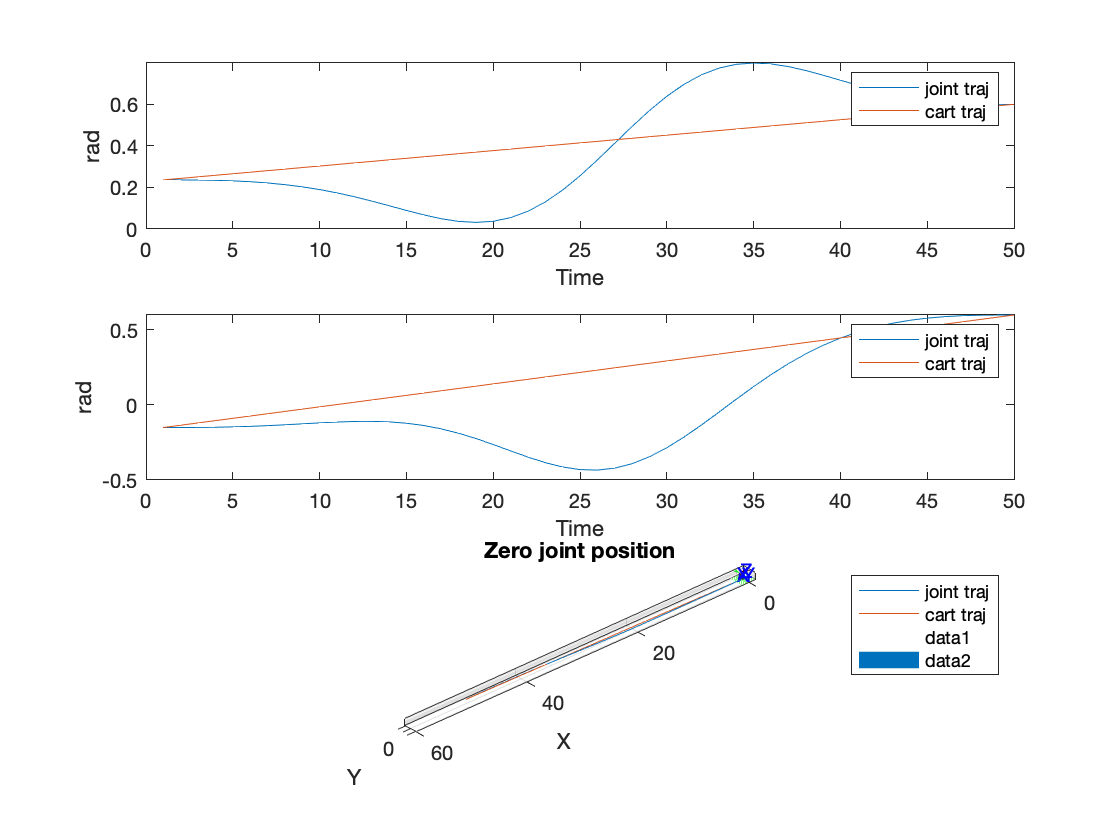

title('Zero joint position')

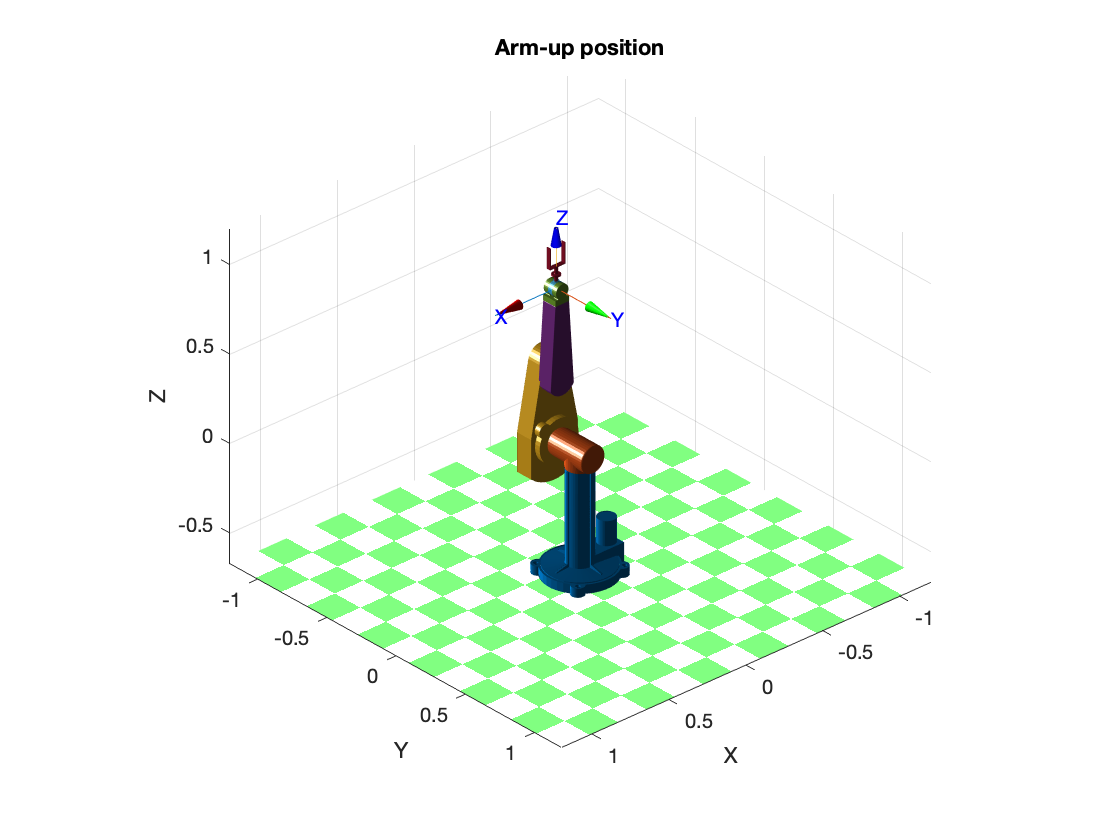

%Arm-up position
clf
p560.plot3d(q2, 'view', ae_angle) 
title('Arm-up position')

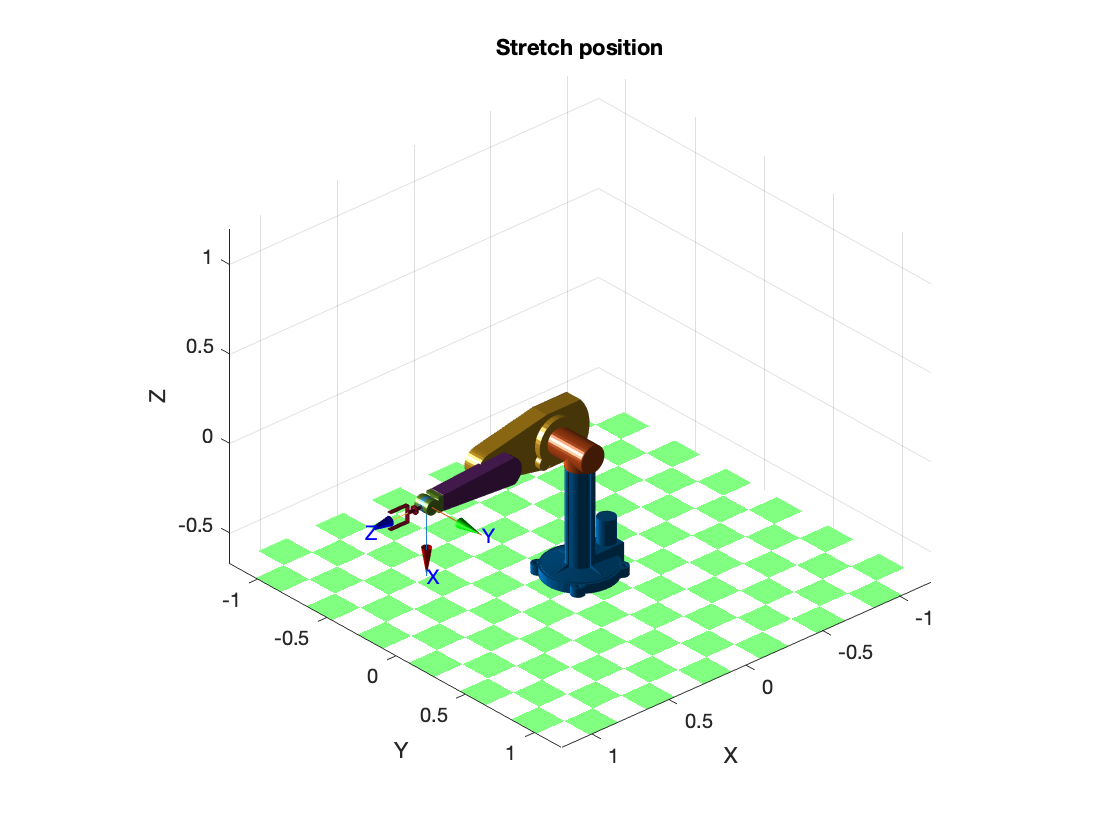

%Stretch Position
clf;
p560.plot3d(q3, 'view', ae_angle)
title('Stretch position')

(b) Suppose that a sphere is inside the robot workspace. The pose of the sphere with respect to the robot base is


$${\;}^R \xi_S =\left\lbrack \begin{array}{cccc}
1 & 0 & 0 & 0\ldotp 6\\
0 & 1 & 0 & 0\ldotp 6\\
0 & 0 & 1 & -0\ldotp 3\\
0 & 0 & 0 & 1
\end{array}\right\rbrack$$


In order to grab the sphere using Puma 560 robot, the robot needs to move to a grasping pose. At the grasping pose, the pose of the robot end-effector with respect to the sphere is:


$${\;}^S \xi_E =\left\lbrack \begin{array}{cccc}
0 & -1 & 0 & 0\\
-1 & 0 & 0 & 0\\
0 & 0 & -1 & 0\ldotp 3\\
0 & 0 & 0 & 1
\end{array}\right\rbrack$$


Calculate the Euler angles of the corresponding rotation matrix. Explain how the rotation sequence is transforming the end-effector’s coordinate system. Visualize the grasping pose (use plot_sphere to visualize the sphere position as well). As another way to understand the rotation process, obtain the rotation axis of the entire rotation operation, and obtain the overall rotation angle with respect to that rotation axis. Use inverse kinematics to find multiple joint configurations that satisfy the grasping pose requirement. One good configuration looks like below: 

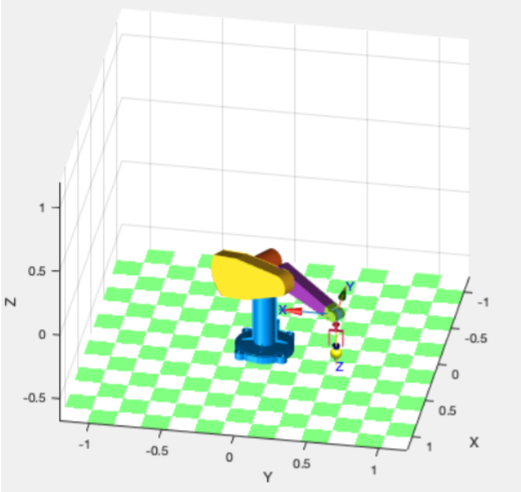

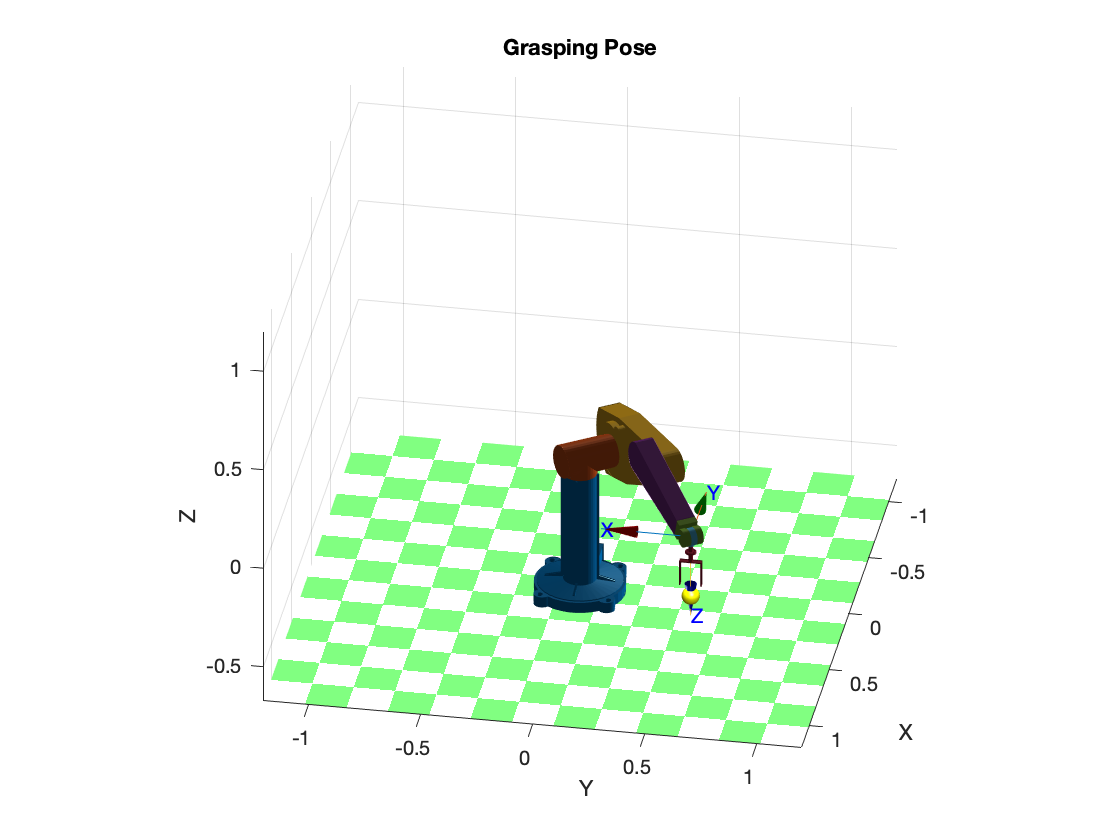

% sphere pose
sphere_pose = transl([0.6,0.6,-0.3]);

% start robot pose
start_joint_pos = [0,pi/3,-pi/3,0,0,0];

% tool center pose
start_TCP_pose = p560.fkine(start_joint_pos);

% construct grasping pose s2e: The following generates the second matrix in parb b
% of problem 1. I will give you this end result, and ask you to develop
% intuitions.
s2e_translate = [0,0,0.3];
s2e_quaternion = UnitQuaternion(0, [sqrt(2)/2, -sqrt(2)/2, 0]);
s2e_pose = transl(s2e_translate)*(s2e_quaternion.T);

% understanding the grasping pose
% obtain the corresponding rotation matrix
R_grasping = s2e_pose(1:3,1:3);

% obtain the Euler angle: angles of the z y z rotation sequence
gammar = tr2eul(R_grasping);

% Obtain the overall rotation axis and angle
[theta_grasp,w_hat_grasp] = trlog(R_grasping);

% compute required end-effector pose for grasping
end_TCP_pose = sphere_pose*s2e_pose;

% obtain the joint angles and visulize required end-effector pose
end_joint_pos = p560.ikine6s(end_TCP_pose);
clf;
plot_sphere(sphere_pose(1:3,4), 0.04, 'y');
p560.plot3d(end_joint_pos, 'view', [100,30])  
title('Grasping Pose')

(c) The robot is initially at a joint position qstart = (0, π/3, −π/3, 0, 0, 0). Compute the robot moving trajectory from the initial pose to the grasping pose. The trajectory should last for 1 seconds, consisting of at least 50 steps. Compute both joint space trajectory (i.e., use jtraj command) and Cartesian trajectory (i.e., use ctraj command). 	

i. For both joint space trajectory and Cartesian trajectory, plot the joint position vs time for the first 3 joints. Compare the two trajectories in joint space, what is your conclusion? 

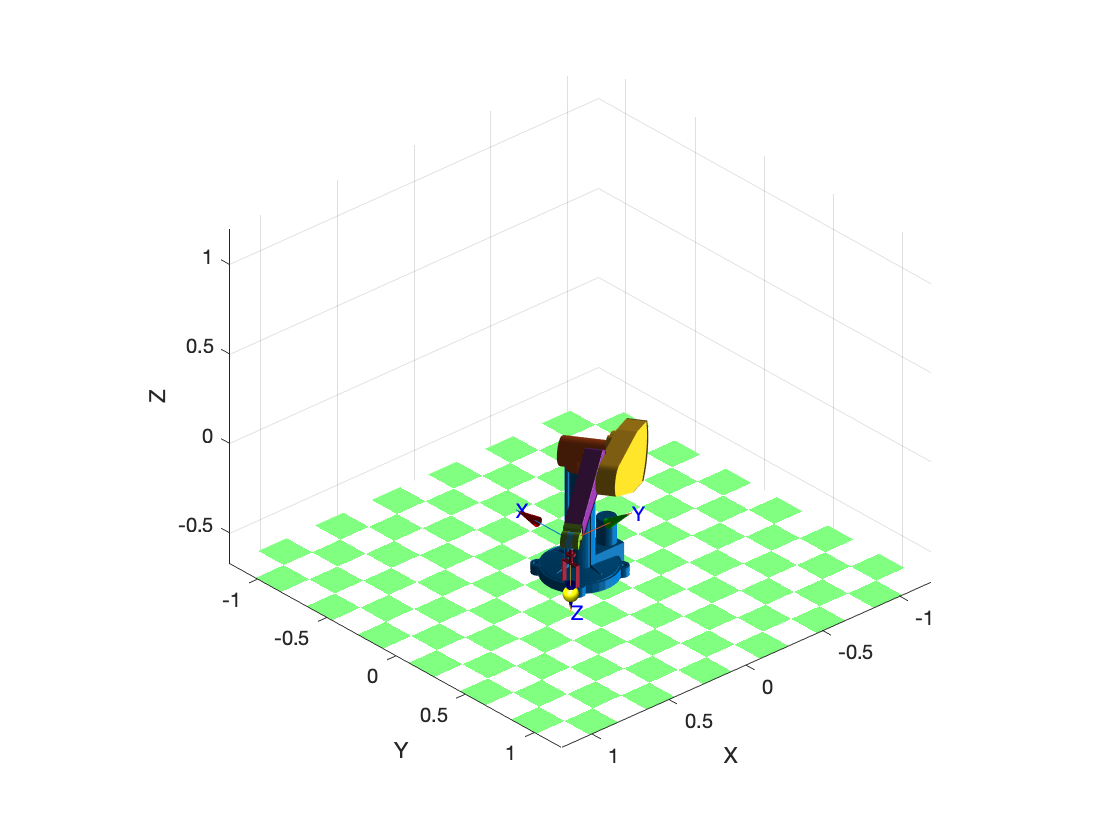

% start robot pose
start_joint_pos = [0,pi/3,-pi/3,0,0,0];

% tool center pose
start_TCP_pose = p560.fkine(start_joint_pos);
    
% construct grasping pose s2e: The following generates the second matrix in parb b
% of problem 1. I will give you this end result, and ask you to develop
% intuitions.
s2e_translate = [0,0,0.3];
s2e_quaternion = UnitQuaternion(0, [sqrt(2)/2, -sqrt(2)/2, 0]);
s2e_pose = transl(s2e_translate)*(s2e_quaternion.T);

% understanding the grasping pose
% obtain the corresponding rotation matrix
R_grasping = s2e_pose(1:3,1:3);

% obtain the Euler angle: angles of the z y z rotation sequence
gammar = tr2eul(R_grasping);

% Obtain the overall rotation axis and angle
[theta_grasp,w_hat_grasp] = trlog(R_grasping);

% compute required end-effector pose for grasping
end_TCP_pose = sphere_pose*s2e_pose; %robot to sphere * sphere to end effector
% obtain the joint angles and visulize required end-effector pose (using
% inverse kinetmatics of a 6 axis robot found using ikine6s()
end_joint_pos = p560.ikine6s(end_TCP_pose);

%% joint space trajectory
joint_traj = jtraj(start_joint_pos, end_joint_pos, linspace(0,1,50));
clf
plot_sphere(sphere_pose(1:3,4), 0.04, 'y');
p560.plot3d(joint_traj, 'view', ae_angle)

%% Cartesian trajecotry
% note: use trnorm() to normalize the homogeneous transformation matrix if 
% you see errors due to numerical precision.
end_TCP_pose = SE3([0.6 0.6 0])*SE3.Rz(gammar(3))*SE3.Ry(gammar(2));
cartesian_traj = ctraj(start_TCP_pose, end_TCP_pose, linspace(0,1,50));
joint_traj2 = p560.ikine6s(cartesian_traj, 'ru');
clf
plot_sphere(sphere_pose(1:3,4), 0.04, 'y');
p560.plot3d(joint_traj, 'view', ae_angle)

%% plot joint trajectory
% TODO: add label for x and y axis
figure,
% joint 1
subplot(3,1,1)
plot(joint_traj(:,1))
hold on
plot(joint_traj2(:,1))
legend('joint traj', 'cart traj')
xlabel('Time')
ylabel('Angle (rad)')

% joint 2
subplot(3,1,2)
plot(joint_traj(:,2))
hold on
plot(joint_traj2(:,2))
legend('joint traj', 'cart traj')
xlabel('Time')
ylabel('Angle (rad)')

% joint 3
subplot(3,1,3)
plot(joint_traj(:,3))
hold on
plot(joint_traj2(:,3))
legend('joint traj', 'cart traj')
xlabel('Time')
ylabel('Angle (rad)')
legend('joint traj', 'cart traj')					

ii. For both joint space trajectory and Cartesian trajectory, plot the end-effector position (translational x,y,z only) vs time. Compare the two trajectories in Cartesian space, what is you conclusion? 		

*MATLAB functions/class methods that might be useful: mdl_puma560, tr2eul, trlog, SerialLink/plot3d, SerialLink/fkine, SerialLink/ikine6s, clf, SE3, subplot. Use MATLAB command help [function] to see usage for [function].* 

%% plot end-effector position trajectory
% calculate end-effector position for joint-based trajectory
% assume 50 points in the generated trajectory
traj1_TCP_pose = SE3(repmat(eye(4),1,1,50));
for i = 1:50
    traj1_TCP_pose(i) = p560.fkine(joint_traj(i,:));
end
T1 = traj1_TCP_pose.T;      % homogeneous transformation matrix for 
                            % joint-based trajectory
T2 = cartesian_traj.T;      % homogeneous transformation matrix for 
                            % Cartesian trajectory

% TODO: add label for x and y axis
figure,
% translational x axis
subplot(3,1,1)
plot(squeeze(T1(1,4,:)))
hold on
plot(squeeze(T2(1,4,:)))
legend('joint traj', 'cart traj')

% translational y axis
subplot(3,1,2)
plot(squeeze(T1(2,4,:)))
hold on
plot(squeeze(T2(2,4,:)))
legend('joint traj', 'cart traj')

% translational z axis
subplot(3,1,3)
plot(squeeze(T1(3,4,:)))
hold on
plot(squeeze(T2(3,4,:)))
legend('joint traj', 'cart traj')

what is your conclusion?

There is an unlimited number of ways to get to the end effector position. To arrive at the final position, both the cartesian trajectory and the joint trajectory has their own paths. However, the cartesian trajectory is linear  whereas the joint trajectory gives smoother trajectory.

2.For the Puma 560 robot, investigate the errors in end-effector pose due to manufacturing errors: 

(a) Make link 2 longer by 0.5 mm. For 100 random joint configurations what is the mean and maximum error in the components of end-effector pose? 							

(b) Introduce an error of +0.1 degree in the joint 2 angle and repeat the analysis above. 						

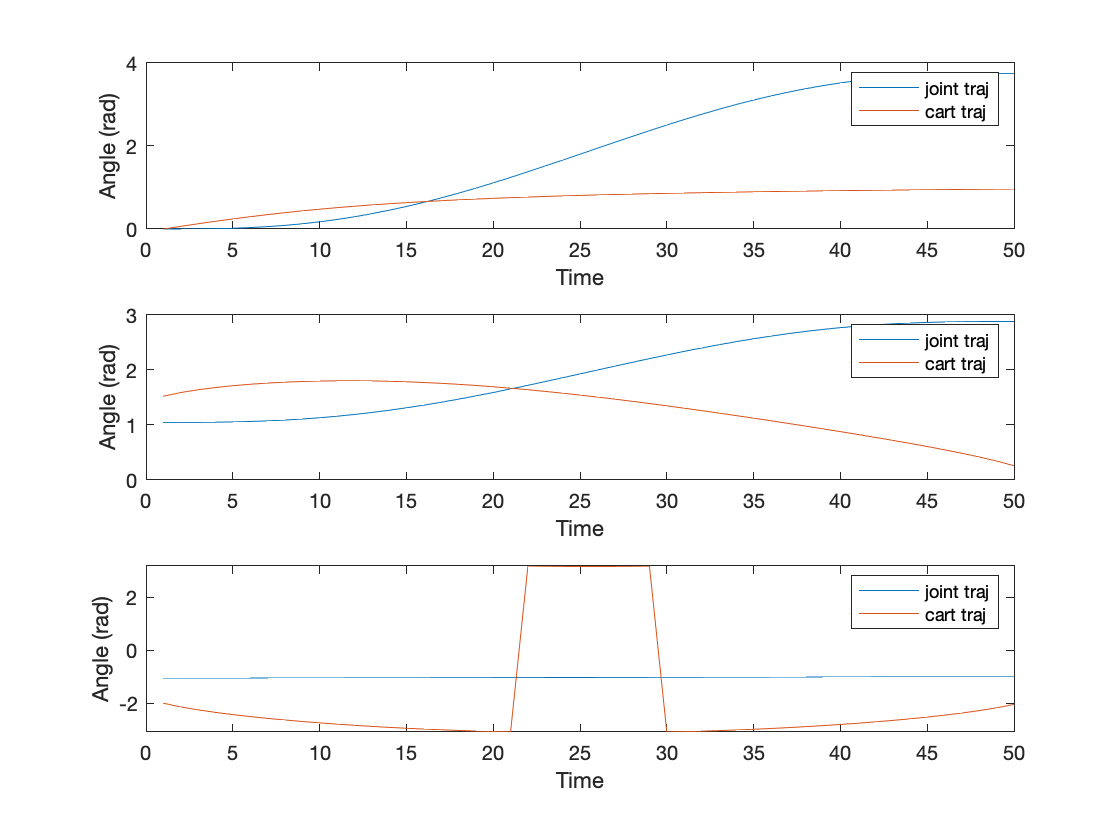

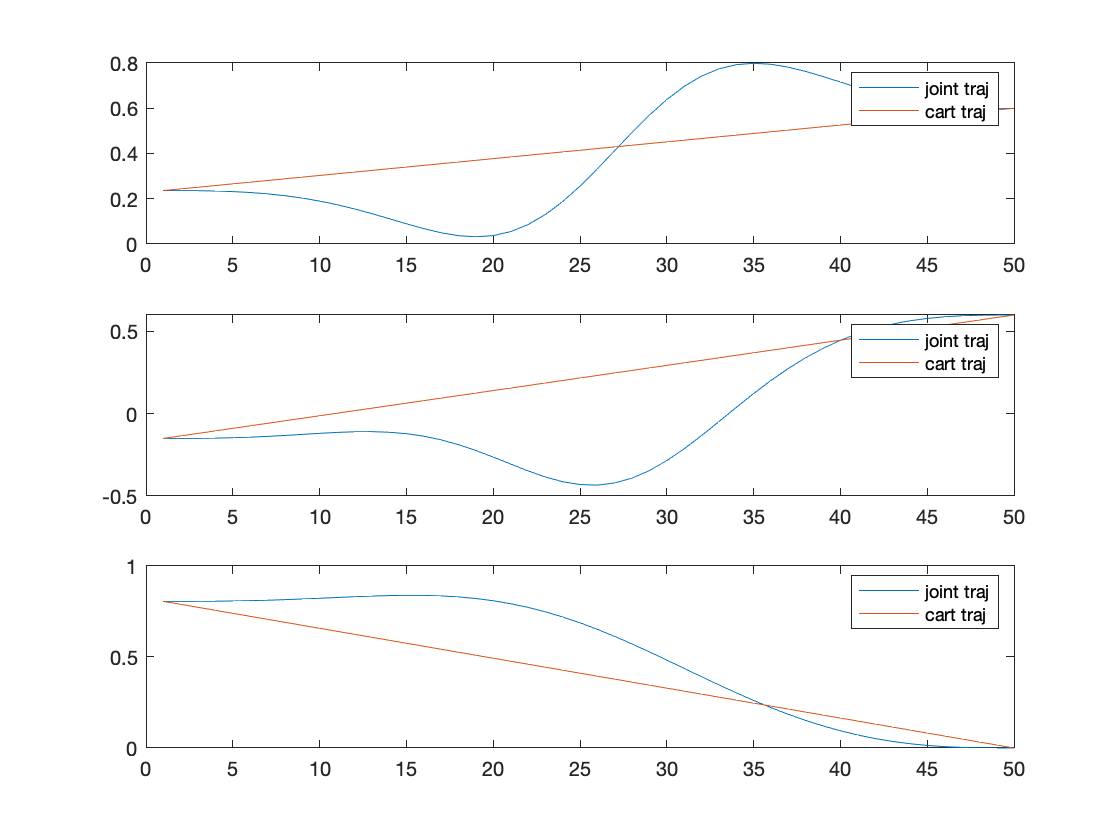

mdl_puma560

%% 2a

N = 100; %100 iterations
q = rand(1,6,N); %random

    T_nom = zeros(4,4,N);
    for i = 1:N
        T_nom(:,:,i) = p560.fkine(q(:,:,i));
    end
    
p560.edit
uiwait 

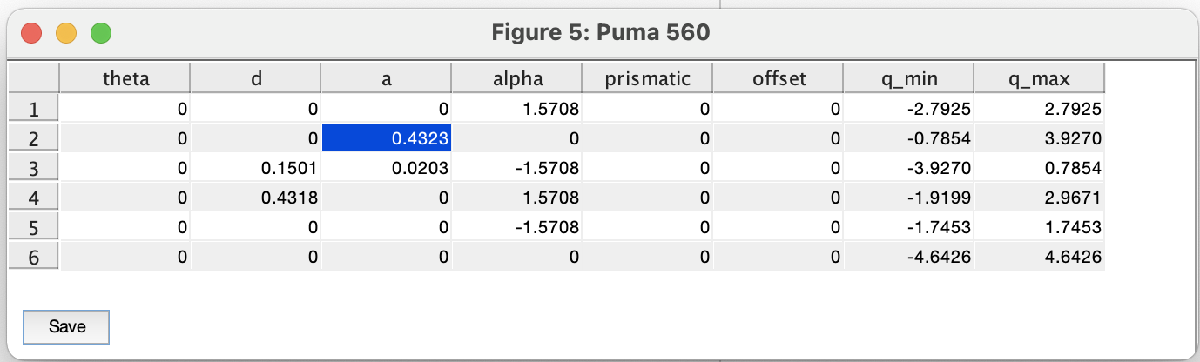

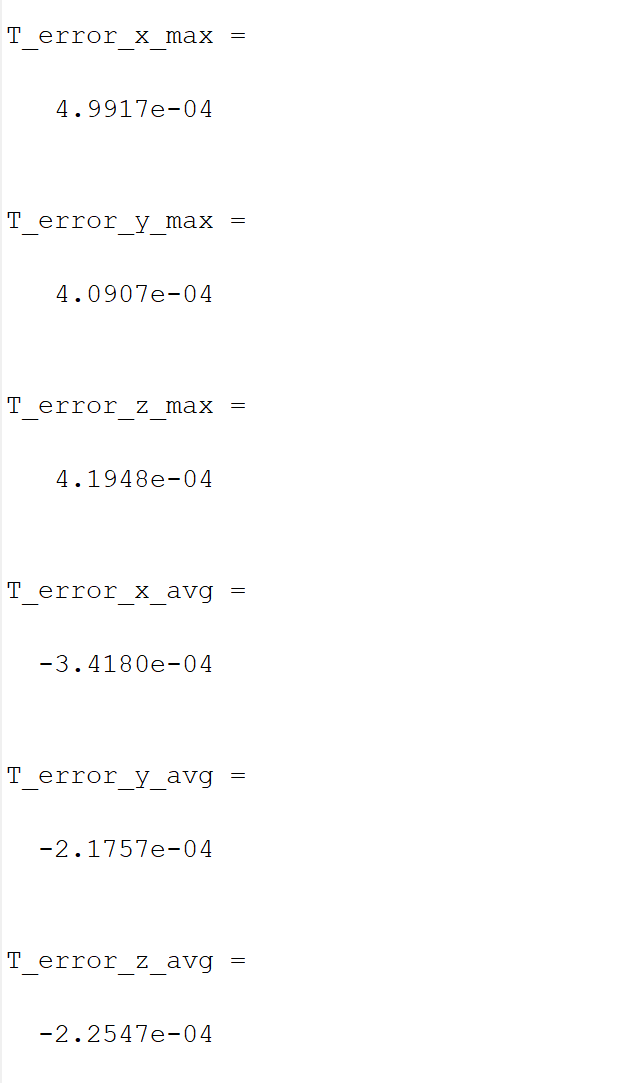


%% error
    T_error = zeros(4,4,N);
    for i = 1:N
        T_error(:,:,i) = p560.fkine(q(:,:,i));
    end
T_nom_t = zeros(3,N); %Nominal translation vector
T_err_t = zeros(3,N); %Error translation vector
% storing translation vectors
    for i = 1:N
        T_nom_t(:,i) = T_nom(1:3,4,i);
        T_err_t(:,i) = T_error(1:3,4,i);
    end

T_error = T_nom_t-T_err_t;

%Max Error
T_error_x_max = max(abs(T_error(1,:))) 

T_error_x_max = 0

T_error_y_max = max(abs(T_error(2,:)))

T_error_y_max = 0

T_error_z_max = max(abs(T_error(3,:))) 

T_error_z_max = 0


%Average Error
T_error_x_avg = mean(T_error(1,:)) 

T_error_x_avg = 0

T_error_y_avg = mean(T_error(2,:)) 

T_error_y_avg = 0

T_error_z_avg = mean(T_error(3,:)) 

T_error_z_avg = 0



%% 2b
q2 = q

q2 = q2(:,:,1) =

    0.3796    0.3191    0.9861    0.7182    0.4132    0.0986


q2(:,:,2) =

    0.7346    0.6373    0.0738    0.1205    0.9816    0.4968


q2(:,:,3) =

    0.0224    0.0538    0.1409    0.8935    0.4658    0.5609


q2(:,:,4) =

    0.4945    0.0678    0.8976    0.2886    0.2690    0.5942


q2(:,:,5) =

    0.4759    0.3683    0.6556    0.9382    0.6204    0.2828


q2(:,:,6) =

    0.2052    0.4391    0.0273    0.8762    0.6101    0.2036


q2(:,:,7) =

    0.5199    0.0538    0.8622    0.4429    0.5480    0.5669


q2(:,:,8) =

    0.6804    0.3714    0.0782    0.4564    0.0478    0.7383


q2(:,:,9) =

    0.0380    0.9542    0.7424    0.9374    0.5134    0.2409


q2(:,:,10) =

    0.2600    0.7590    0.9933    0.3567    0.7529    0.1100


q2(:,:,11) =

    0.5970    0.4306    0.7307    0.2612    0.0948    0.4510


q2(:,:,12) =

    0.6401    0.1320    0.4528    0.6522    0.8270    0.3081


q2(:,:,13) =

    0.4024    0.8842    0.7006    0.2419    0.7598    0.2909


q2(

q2(:,2,:) = q2(:,2,:) + 0.1/180*pi

q2 = q2(:,:,1) =

    0.3796    0.3208    0.9861    0.7182    0.4132    0.0986


q2(:,:,2) =

    0.7346    0.6391    0.0738    0.1205    0.9816    0.4968


q2(:,:,3) =

    0.0224    0.0556    0.1409    0.8935    0.4658    0.5609


q2(:,:,4) =

    0.4945    0.0695    0.8976    0.2886    0.2690    0.5942


q2(:,:,5) =

    0.4759    0.3701    0.6556    0.9382    0.6204    0.2828


q2(:,:,6) =

    0.2052    0.4409    0.0273    0.8762    0.6101    0.2036


q2(:,:,7) =

    0.5199    0.0556    0.8622    0.4429    0.5480    0.5669


q2(:,:,8) =

    0.6804    0.3731    0.0782    0.4564    0.0478    0.7383


q2(:,:,9) =

    0.0380    0.9560    0.7424    0.9374    0.5134    0.2409


q2(:,:,10) =

    0.2600    0.7607    0.9933    0.3567    0.7529    0.1100


q2(:,:,11) =

    0.5970    0.4323    0.7307    0.2612    0.0948    0.4510


q2(:,:,12) =

    0.6401    0.1338    0.4528    0.6522    0.8270    0.3081


q2(:,:,13) =

    0.4024    0.8860    0.7006    0.2419    0.7598    0.2909


q2(


%% error
    T_error = zeros(4,4,N);
    for i = 1:N
        T_error(:,:,i) = p560.fkine(q2(:,:,i));
    end
T_error_t2 = zeros(3,N); %Error translation vector
% storing translation vectors
    for i = 1:N
        T_error_t2(:,i) = T_error(1:3,4,i);
    end

T_error2 = T_nom_t-T_error_t2;

%Max Error
T_error_x_max = max(abs(T_error2(1,:))) 

T_error_x_max = 0.0010

T_error_y_max = max(abs(T_error2(2,:)))

T_error_y_max = 7.9958e-04

T_error_z_max = max(abs(T_error2(3,:))) 

T_error_z_max = 6.4080e-04


%Mean error
T_error_x_avg = mean(T_error2(1,:)) 

T_error_x_avg = 6.2555e-04

T_error_y_avg = mean(T_error2(2,:)) 

T_error_y_avg = 3.2999e-04

T_error_z_avg = mean(T_error2(3,:)) 

T_error_z_avg = -3.5204e-05

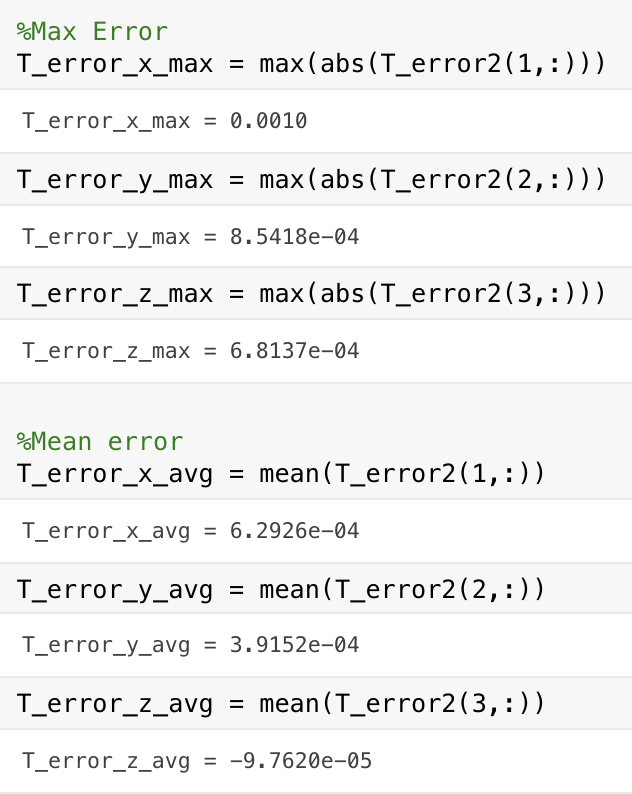

3. Show that mathematically, operations of consecutive rotation around and translation along the same axis commute. In other words: 


$$T_x \left(a\right)R_x \left(\theta \right)=R_x \left(\theta \right)T_x \left(a\right)$$


 
$$T_y \left(a\right)R_y \left(\theta \right)=R_y \left(\theta \right)T_y \left(a\right)$$


 
$$T_z \left(a\right)R_z \left(\theta \right)=R_z \left(\theta \right)T_z \left(a\right)$$


where Ti and Ri are, respectively, the homogeneous transformation matrices of pure translation and rotation operations.We used these facts in DH-parameter analysis.

### *Solution*


$$A={\textrm{rot}}_z \left(\theta_i \right)\cdot {\textrm{trans}}_z \left(d_i \right)\cdot {\textrm{trans}}_x \left(a_i \right)\cdot {\textrm{rot}}_x \left(\alpha_i \right)$$


Where,

${\textrm{rot}}_z \left(\theta_i \right)=\left\lbrack \begin{array}{cccc}
\cos \;\theta_i  & -\sin \;\theta_i  & 0 & 0\\
\sin \;\theta_i  & \cos \;\theta_i  & 0 & 0\\
0 & 0 & 1 & 0\\
0 & 0 & 0 & 1
\end{array}\right\rbrack$,${\;\textrm{trans}}_z \left(d_i \right)$=$\left\lbrack \begin{array}{cccc}
1 & 0 & 0 & 0\\
0 & 1 & 0 & 0\\
0 & 0 & 1 & d_i \\
0 & 0 & 0 & 1
\end{array}\right\rbrack$, ${\textrm{trans}}_x \left(a_i \right)=\left\lbrack \begin{array}{cccc}
1 & 0 & 0 & a_i \\
0 & 1 & 0 & 0\\
0 & 0 & 1 & 0\\
0 & 0 & 0 & 1
\end{array}\right\rbrack$


$${\textrm{rot}}_x \left(\alpha_i \right)=\left\lbrack \begin{array}{cccc}
1 & 0 & 0 & 0\\
0 & \cos \;\alpha_i  & -\sin \;\alpha_i  & 0\\
0 & \sin \;\alpha_i  & \cos \;\alpha_i  & 0\\
0 & 0 & 0 & 1
\end{array}\right\rbrack$$


For X axis, ${\textrm{rot}}_x \left(\theta \right)\cdot {\textrm{trans}}_x \left(a_i \right)$should be equal to ${\textrm{trans}}_z \left(a_i \right)\cdot {\textrm{rot}}_z \left(\theta \right)$


$${\textrm{rot}}_x \left(\theta \right)\cdot {\textrm{trans}}_x \left(a_i \right)=\left\lbrack \begin{array}{cccc}
1 & 0 & 0 & 0\\
0 & \cos \;\alpha_i  & -\sin \;\alpha_i  & 0\\
0 & \sin \;\alpha_i  & \cos \;\alpha_i  & 0\\
0 & 0 & 0 & 1
\end{array}\right\rbrack \cdot \left\lbrack \begin{array}{cccc}
1 & 0 & 0 & a_i \\
0 & 1 & 0 & 0\\
0 & 0 & 1 & 0\\
0 & 0 & 0 & 1
\end{array}\right\rbrack =\left\lbrack \begin{array}{cccc}
1 & 0 & 0 & a_i \\
0 & \cos \;\alpha_i  & -\sin \;\alpha_i  & 0\\
0 & \sin \;\alpha_i  & \cos \;\alpha_i  & 0\\
0 & 0 & 0 & 1
\end{array}\right\rbrack$$



$${\textrm{trans}}_z \left(a_i \right)\cdot {\textrm{rot}}_z \left(\theta \right)\Rightarrow \left\lbrack \begin{array}{cccc}
1 & 0 & 0 & a_i \\
0 & 1 & 0 & 0\\
0 & 0 & 1 & 0\\
0 & 0 & 0 & 1
\end{array}\right\rbrack \cdot \left\lbrack \begin{array}{cccc}
1 & 0 & 0 & 0\\
0 & \cos \;\alpha_i  & -\sin \;\alpha_i  & 0\\
0 & \sin \;\alpha_i  & \cos \;\alpha_i  & 0\\
0 & 0 & 0 & 1
\end{array}\right\rbrack =\left\lbrack \begin{array}{cccc}
1 & 0 & 0 & a_i \\
0 & \cos \;\alpha_i  & -\sin \;\alpha_i  & 0\\
0 & \sin \;\alpha_i  & \cos \;\alpha_i  & 0\\
0 & 0 & 0 & 1
\end{array}\right\rbrack$$


For Y axis, ${\textrm{rot}}_y \left(\Theta \right)\cdot {\textrm{trans}}_y \left(c_i \right)$ should be equal to ${\textrm{trans}}_y \left(c_i \right)\cdot {\textrm{rot}}_y \left(\Theta \right)$


$${\textrm{rot}}_y \left(\Theta \right)\cdot {\textrm{trans}}_y \left(c_i \right)=\left\lbrack \begin{array}{cccc}
\cos \;\Theta_i  & 0 & \sin \;\Theta_i  & 0\\
0 & 1 & 0 & 0\\
-\sin \;\Theta_i  & 0 & \cos \;\Theta_i  & 0\\
0 & 0 & 0 & 1
\end{array}\right\rbrack \cdot \left\lbrack \begin{array}{cccc}
1 & 0 & 0 & 0\\
0 & 1 & 0 & c_i \\
0 & 0 & 1 & 0\\
0 & 0 & 0 & 1
\end{array}\right\rbrack =\left\lbrack \begin{array}{cccc}
\cos \;\Theta_i  & 0 & \sin \;\Theta_i  & 0\\
0 & 1 & 0 & c_i \\
-\sin \;\Theta_i  & 0 & \cos \;\Theta_i  & 0\\
0 & 0 & 0 & 1
\end{array}\right\rbrack$$



$${\textrm{trans}}_y \left(c_i \right)\cdot {\textrm{rot}}_y \left(\Theta \right)=\left\lbrack \begin{array}{cccc}
1 & 0 & 0 & 0\\
0 & 1 & 0 & c_i \\
0 & 0 & 1 & 0\\
0 & 0 & 0 & 1
\end{array}\right\rbrack \cdot \left\lbrack \begin{array}{cccc}
\cos \;\Theta_i  & 0 & \sin \;\Theta_i  & 0\\
0 & 1 & 0 & 0\\
-\sin \;\Theta_i  & 0 & \cos \;\Theta_i  & 0\\
0 & 0 & 0 & 1
\end{array}\right\rbrack =\left\lbrack \begin{array}{cccc}
\cos \;\Theta_i  & 0 & \sin \;\Theta_i  & 0\\
0 & 1 & 0 & c_i \\
-\sin \;\Theta_i  & 0 & \cos \;\Theta_i  & 0\\
0 & 0 & 0 & 1
\end{array}\right\rbrack$$


For Z axis, ${\textrm{rot}}_z \left(\theta \right)\cdot {\textrm{trans}}_z \left(d\right)$should be equal to ${\textrm{trans}}_z \left(d\right)\cdot {\textrm{rot}}_z \left(\theta \right)$


$${\textrm{rot}}_z \left(\theta \right)\cdot {\textrm{trans}}_z \left(d\right)\Rightarrow \left\lbrack \begin{array}{cccc}
\cos \;\theta_i  & -\sin \;\theta_i  & 0 & 0\\
\sin \;\theta_i  & \cos \;\theta_i  & 0 & 0\\
0 & 0 & 1 & 0\\
0 & 0 & 0 & 1
\end{array}\right\rbrack \cdot \left\lbrack \begin{array}{cccc}
1 & 0 & 0 & 0\\
0 & 1 & 0 & 0\\
0 & 0 & 1 & d_i \\
0 & 0 & 0 & 1
\end{array}\right\rbrack =\left\lbrack \begin{array}{cccc}
\cos \;\theta_i  & -\sin \;\theta_i  & 0 & 0\\
\sin \;\theta_i  & \cos \;\theta_i  & 0 & 0\\
0 & 0 & 1 & d_i \\
0 & 0 & 0 & 1
\end{array}\right\rbrack$$



$${\textrm{trans}}_z \left(d\right)\cdot {\textrm{rot}}_z \left(\theta \right)\Rightarrow \left\lbrack \begin{array}{cccc}
1 & 0 & 0 & 0\\
0 & 1 & 0 & 0\\
0 & 0 & 1 & d_i \\
0 & 0 & 0 & 1
\end{array}\right\rbrack \cdot \left\lbrack \begin{array}{cccc}
\cos \;\theta_i  & -\sin \;\theta_i  & 0 & 0\\
\sin \;\theta_i  & \cos \;\theta_i  & 0 & 0\\
0 & 0 & 1 & 0\\
0 & 0 & 0 & 1
\end{array}\right\rbrack =\left\lbrack \begin{array}{cccc}
\cos \;\theta_i  & -\sin \;\theta_i  & 0 & 0\\
\sin \;\theta_i  & \cos \;\theta_i  & 0 & 0\\
0 & 0 & 1 & d_i \\
0 & 0 & 0 & 1
\end{array}\right\rbrack$$


From the above, regardless of the multiplication order, the results of multiplicaiton are the same.